% wave buoy processing

 

%load aws_acc_data;

 

%acc = vert_acc_1; % this data doesn't look super great, but shows something

%acc = vert_acc_2; % this data is actually maybe not bad????

acc = y;
 

 

L = 1024;  % pick something reasonable. 1024 is fast for ffts, but its not important.

F = 5; % 5 Hz sampling

T = 1/F;  % convert to frequency

t = (0:L-1)*T;  % time dimension

x = acc(1:L)  % select the data

x =     8.4069
    8.2860
    9.4203
    9.8433
    9.4107
    8.9781
   10.5886
   11.5639
   10.3330
    9.5931


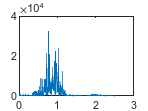


x = fillmissing(x,'movmean',5); % interpolate over any NaNs (otherwise fft won't work)

meanx = nanmean(x);

x = x - meanx; % tries to get rid of the DC component, because it is HUGE!

 

 

y = fft(x);

P = abs(y).^2;   %convert to power

P1 = P(1:L/2+1);  % select half the data (the fft returns both +vs and -ve frequencies)

P1(2:end-1) = 2*P1(2:end-1); 

f = F*(0:(L/2))/L; % set the frequency scale properly for half the data

plot(f(1:L/2),P1(1:L/2)); % you can start from 2 if there is a big DC component, but this works ok.

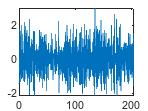


 

T = (2*pi*f).^2';  %the transfer function for vertical acceleration (take transform to get dimension correct)

E = P1./T;

 

figure(1);

plot(t,x);


figure(2);

plot(f,P1); % plot just the power spectrum to see the peaks.

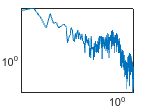


% this plot shows peak power around 1 Hz, which is maybe about what

% we saw, and another peak around 0.5 Hz. That seems reasonable?

figure(3);

loglog(f(1:512),E(1:512));  % plot the heave spectrum

%hold on
%theoretical_spectra = (2*pi*0.012*2.5*9.8*u.*f.^(-4))/8*pi.^4;
%loglog(f(1:512), theoretical_spectra(1:512), DisplayName="10mph theoretical result")
%hold off

% this plot isn't super great, and we may be getting something that looks ok-ish

% just because the transfer function kinds makes noise have an f^-4 drop off.

% but it does look roughly f^-4 even in the denser data area. May be luck,

% but reasonable.  the peaks at ~0.5 and 1 Hz are evident.